clear all;
run("load_params_ResonantCase.m");

# 2.2 Position PID-controller

## 2.2.1

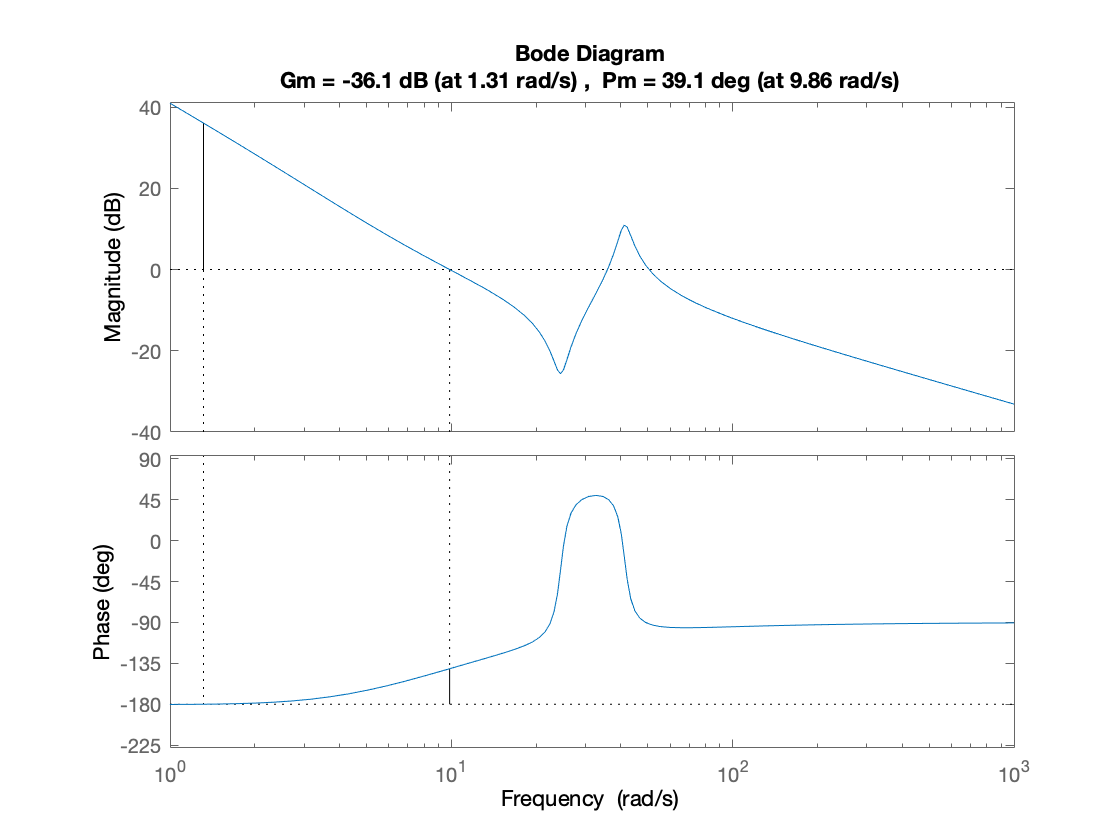

% Position controller specs
pctrl.ts = 0.85; % Desired settling time (at 5%)
pctrl.Mp = 0.3; % Desired overshoot

% Get specs for loop tf 
pctrl.d = log(1/pctrl.Mp) / sqrt(pi^2 + log(1/pctrl.Mp)^2); % Damping factor
pctrl.wgc = 3/pctrl.d/pctrl.ts; % Gain crossover freq [rad/s]          
pctrl.phim = 180/pi * atan(2*pctrl.d/sqrt(sqrt(1+4*pctrl.d^4)-2*pctrl.d^2)); % Phase margin [deg]

% Bode Method
[PID.kp, PID.ki, PID.kd] = BodMet(pctrl.wgc,pctrl.phim,simp_model.P_u_thh);

% Controller
s = tf('s');
PID.C = PID.kp + PID.ki/s + PID.kd*s; % Controller

% Verify frequency specs
figure;
margin(PID.C*simp_model.P_u_thh);

% Real derivator
PID.Tl = 1/(10*pctrl.wgc);

% Anti-Windup
AW.Kw = 5/pctrl.ts;

## 2.2.2 

% Open Simulink model
open_system('Simulink/PID.slx');

#### Simulations results [50°]

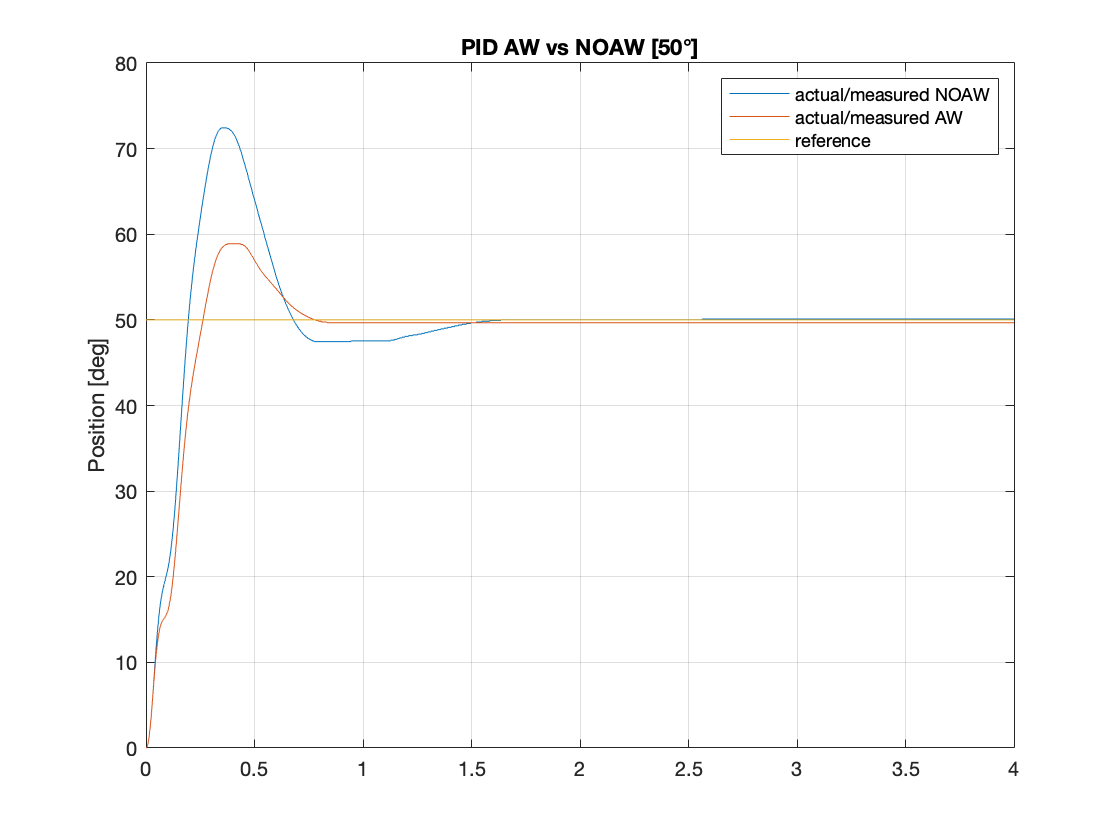

% Set parameters
set_param('PID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '4');
% Step
set_param('PID/Step','Time','0','Before','0','After','50');
set_param('PID/Step1','Time','0','Before','0','After','50');

% AW
set_param('PID/Enable_AW','Value','0'); % Disable AW
set_param('PID/Enable_AW1','Value','1'); % Enable AW

% Run simulation
sim('PID');

% Extract simulation results
PID.t = simres.time; % time vector 
PID.thh_NOAW = simres.signals(1).values(:,1); % hub position NOAW
PID.thh_AW = simres.signals(1).values(:,2); % hub position AW
PID.thh_Ref = simres.signals(1).values(:,3); % hub position reference


% Plot simulation results
figure
plot(PID.t, PID.thh_NOAW);
hold on;
plot(PID.t, PID.thh_AW);
hold on;
plot(PID.t, PID.thh_Ref);
ylabel('Position [deg]');
grid on;
title('PID AW vs NOAW [50°]');
legend('actual/measured NOAW', 'actual/measured AW', 'reference');

#### Simulations results [120°]

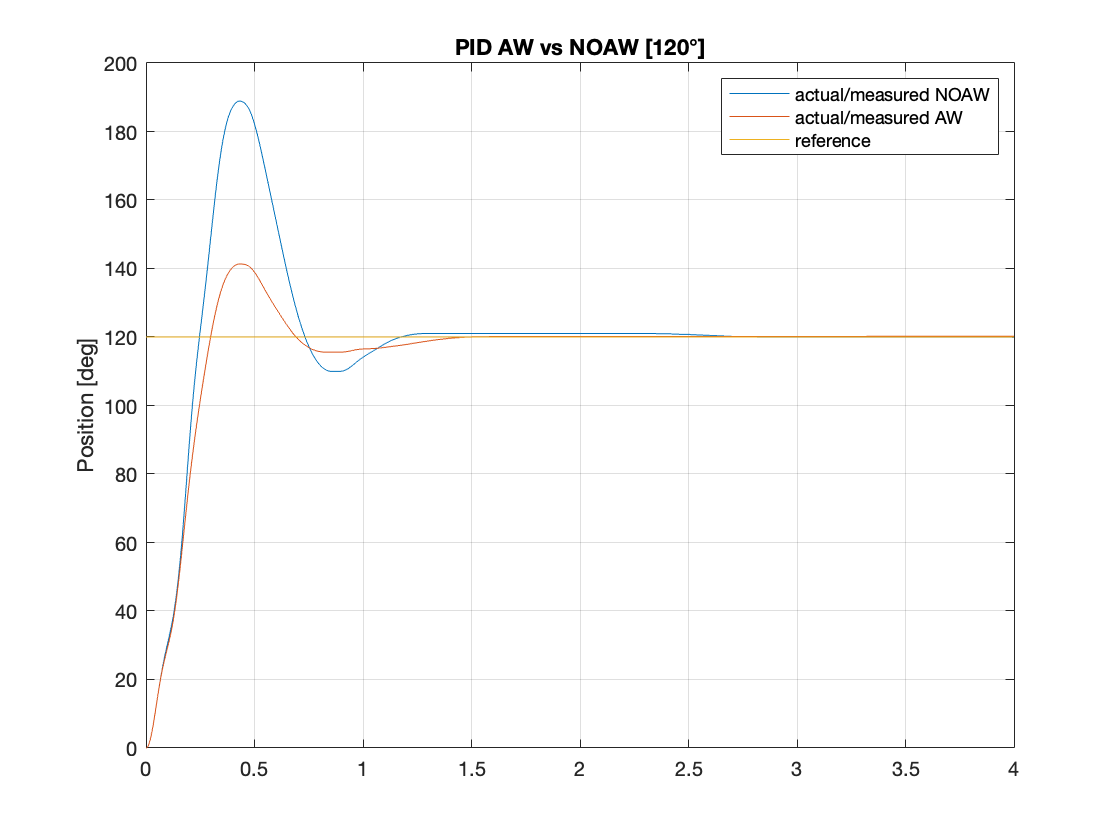

% Set parameters
set_param('PID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '4');
% Step
set_param('PID/Step','Time','0','Before','0','After','120');
set_param('PID/Step1','Time','0','Before','0','After','120');

% Run simulation
sim('PID');

% Extract simulation results
PID.t = simres.time; % time vector 
PID.thh_NOAW = simres.signals(1).values(:,1); % hub position NOAW
PID.thh_AW = simres.signals(1).values(:,2); % hub position AW
PID.thh_Ref = simres.signals(1).values(:,3); % hub position reference


% Plot simulation results
figure
plot(PID.t, PID.thh_NOAW);
hold on;
plot(PID.t, PID.thh_AW);
hold on;
plot(PID.t, PID.thh_Ref);
ylabel('Position [deg]');
grid on;
title('PID AW vs NOAW [120°]');
legend('actual/measured NOAW', 'actual/measured AW', 'reference');

# 2.3 Position state–space control using eigenvalues placement design methods

% State-space model [th_h th_d w_h w_d]
state_space.A = [0 0 1 0;0 0 0 1;0 simp_model.k/(gbox.N^2*simp_model.Jeq) -(simp_model.Beq + mot.Kt*mot.Ke/simp_model.Req)/simp_model.Jeq 0;0 -simp_model.k/simp_model.Jb-simp_model.k/(simp_model.Jeq*gbox.N^2) -simp_model.Bb/simp_model.Jb+(simp_model.Beq+mot.Kt*mot.Ke/simp_model.Req)/(simp_model.Jeq) -simp_model.Bb/simp_model.Jb];
state_space.B = [0;0;mot.Kt*drv.dcgain/(gbox.N*simp_model.Jeq*simp_model.Req);-mot.Kt*drv.dcgain/(gbox.N*simp_model.Jeq*simp_model.Req)];
state_space.Bd = [0;0;-1/(gbox.N^2*simp_model.Jeq);1/(gbox.N^2*simp_model.Jeq)];
state_space.C = [1 0 0 0];

% Real derivative
der.wc = 2*pi*50;
der.d = 1/sqrt(2);
der.NUM = [der.wc^2 0];
der.DEN = [1 2*der.d*der.wc der.wc^2];


## 2.3.1 Nominal action

% Eigenvalues placement
eig.delta = log(1/pctrl.Mp)/(sqrt(pi^2 + log(1/pctrl.Mp)^2));
eig.wn = 3/(eig.delta*pctrl.ts);
eig.phi = atan2(sqrt(1-eig.delta^2),eig.delta);
nominal.lambda1 = eig.wn*exp(1i*(-pi+eig.phi));
nominal.lambda2 = eig.wn*exp(1i*(-pi-eig.phi));
nominal.lambda3 = eig.wn*exp(1i*(-pi+eig.phi/2));
nominal.lambda4 = eig.wn*exp(1i*(-pi-eig.phi/2));
nominal.lambdas = [nominal.lambda1 nominal.lambda2 nominal.lambda3 nominal.lambda4];

% Controller K
nominal.K = acker(state_space.A, state_space.B, nominal.lambdas);


% Nx, Nu
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;0;0;1]);
nominal.N_x = nominal.X(1:4,:);
nominal.N_u = nominal.X(5,:);

## 2.3.2

% Open Simulink model
open_system('Simulink/SS_eig.slx');

#### Simulations results [50°] 

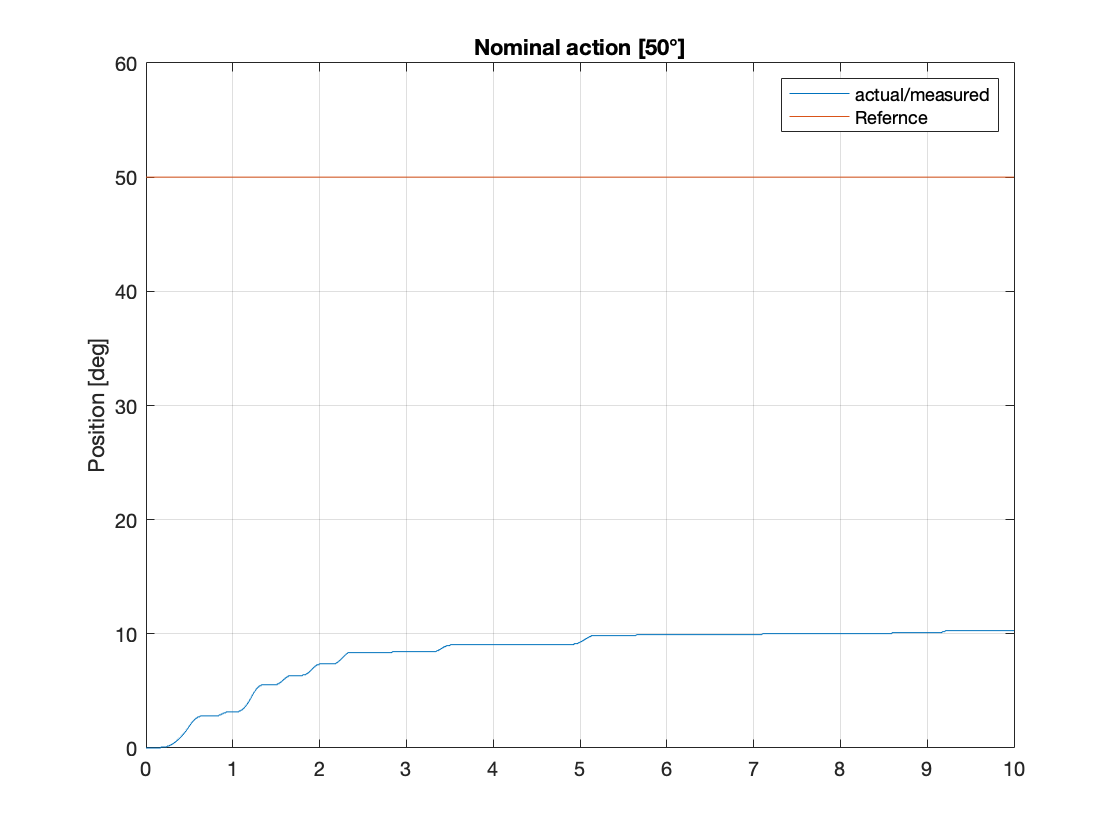

% Set parameters
set_param('SS_eig', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '10');
% Step
set_param('SS_eig/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig/Enable Integral','Value','0'); % Nominal action ON
set_param('SS_eig/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig/State-space Controller/State feedback gain','gain','nominal.K'); % State feedback gain
set_param('SS_eig/State-space Controller/Ki','Gain','0'); % Integral gain

% Run simulation
sim('SS_eig');

% Extract simulation results
nominal.t = simres.time; % Time vector 
nominal.thh = simres.signals(1).values(:,1); % Hub position
nominal.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(nominal.t, nominal.thh);
hold on;
plot(nominal.t, nominal.Ref);
ylabel('Position [deg]');
ylim([0,60]);
grid on;
title('Nominal action [50°]');
legend('actual/measured', 'Refernce');

## 2.3.3 Integral action [OPTIONAL]

% Ae, Be, Ce 
robust.Ae = [0 state_space.C;[0;0;0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Eigenvalues
robust.lambda1 = nominal.lambda1;
robust.lambda2 = nominal.lambda2;
robust.lambda3 = nominal.lambda3;
robust.lambda4 = nominal.lambda4;
robust.lambda5 = -eig.wn;
robust.lambdas = [robust.lambda1 robust.lambda2 robust.lambda3 robust.lambda4 robust.lambda5];

% Ke = [Ki, K]
robust.Ke = acker(robust.Ae, robust.Be, robust.lambdas);

robust.Ki = robust.Ke(:,1);
robust.K = robust.Ke(1,2:5);

## 2.3.4

#### Simulations results [50°] 

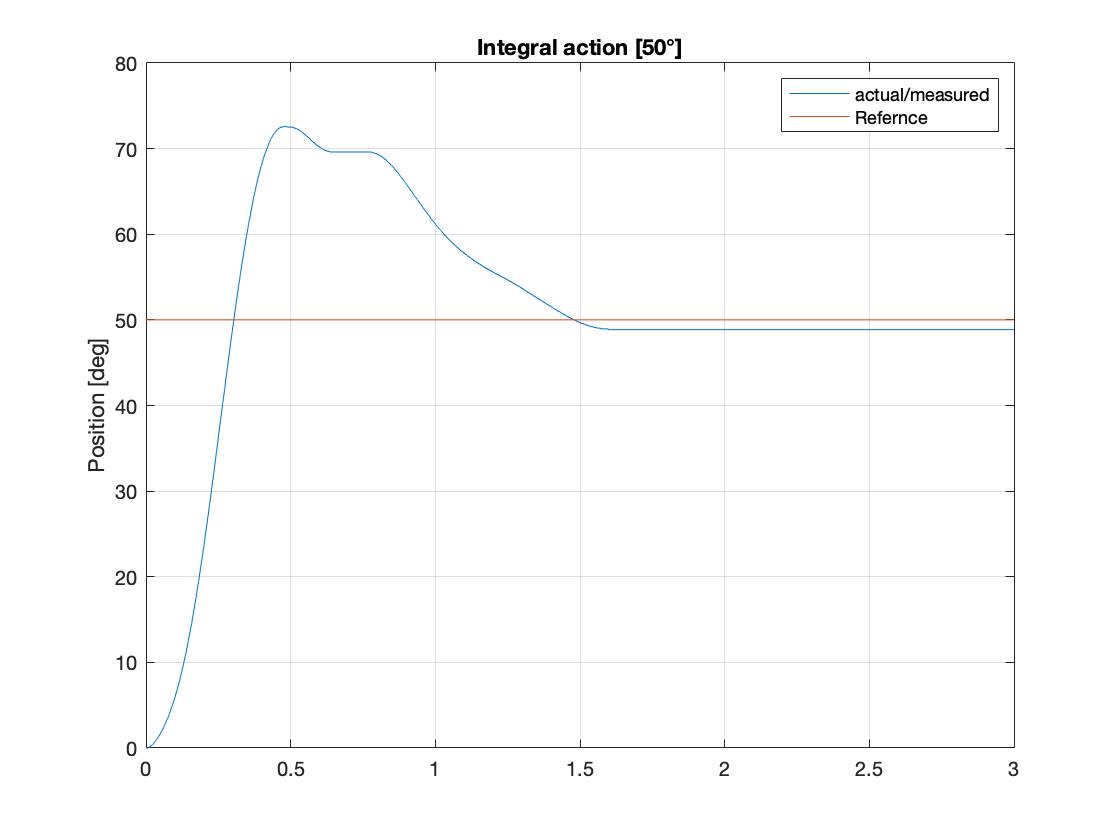

% Set parameters
set_param('SS_eig', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');

% State-space Controller
set_param('SS_eig/Enable Integral','Value','1'); % Integral action ON
set_param('SS_eig/State-space Controller/State feedback gain','gain','robust.K'); % State feedback gain
set_param('SS_eig/State-space Controller/Ki','Gain','robust.Ki'); % Integral gain

% Run simulation
sim('SS_eig');

% Extract simulation results
robust.t = simres.time; % Time vector 
robust.thh = simres.signals(1).values(:,1); % Hub position
robust.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(robust.t, robust.thh);
hold on;
plot(robust.t, robust.Ref);
ylabel('Position [deg]');
ylim([0,80]);
grid on;
title('Integral action [50°]');
legend('actual/measured', 'Refernce');

# 2.4 Position state–space control using LQR methods

# NOMINAL

## 2.4.1 LQR, $\bf{J = \int_0^{+\infty} {\theta_h^2 + ru^2(t)dt}}$

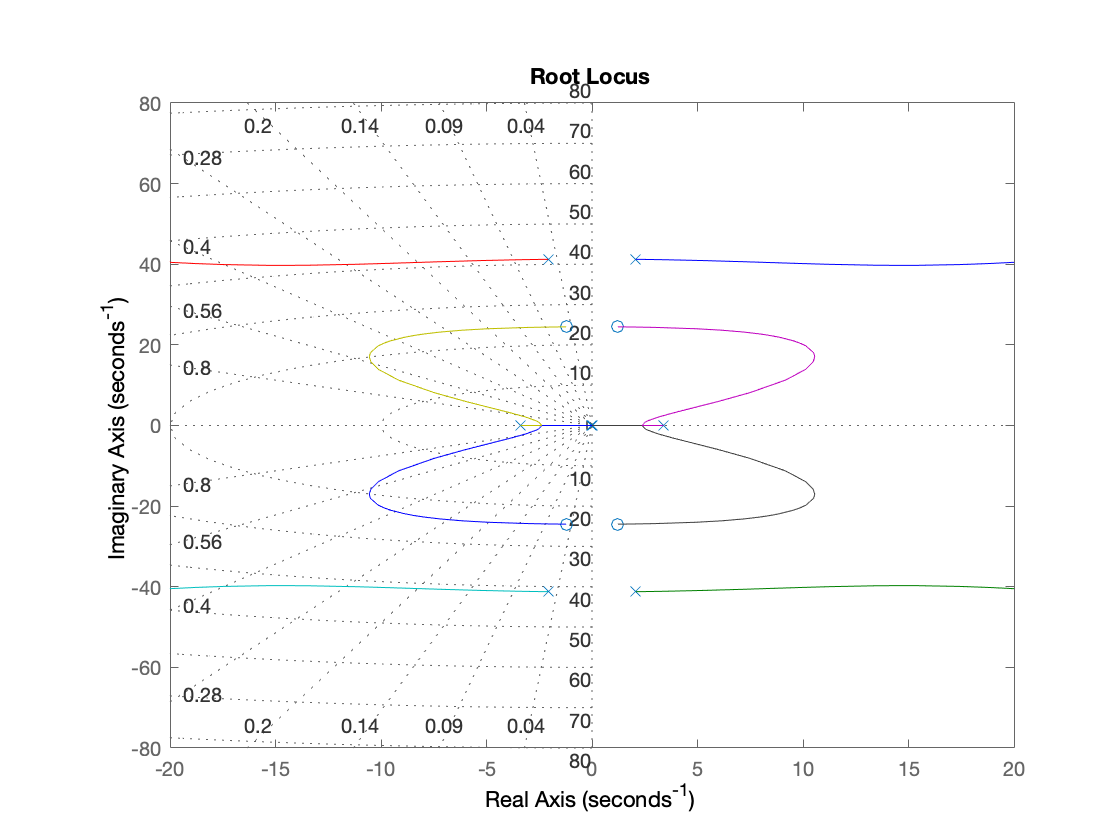

% G(s), G(-s)
lqr_app.sysG = ss(state_space.A,state_space.B,state_space.C,0);
lqr_app.sysGp = ss(-state_space.A,-state_space.B,state_space.C,0);

% Eigs has to have Re <= sigma, Angle
lqr_app.sigma = -3/pctrl.ts;
lqr_app.phi = eig.phi;

% Root locus of 1/r*G(s)*G(-s)
figure
rlocus(lqr_app.sysG*lqr_app.sysGp);
grid on;
xlim([-20,20]);
ylim([-80,80]);

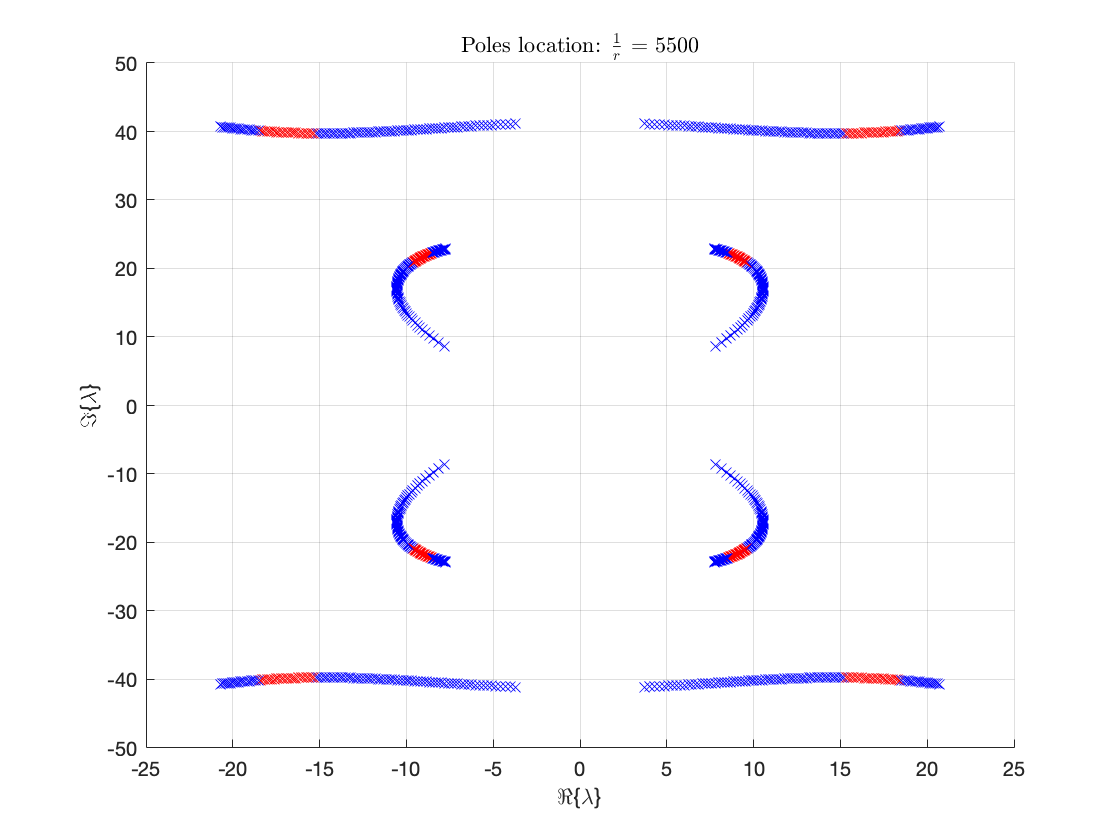

% Plot root locus poles
h = 1;
r_inv_set = zeros(1,3500);
figure;
hold on;
grid on;
xlabel('\Re\{\lambda\}');
ylabel('\Im\{\lambda\}');
poles_notSat = [];
poles_sat = [];
for r_inv = (200:50:5500)
    eigs_for_r = transpose(rlocus(lqr_app.sysG*lqr_app.sysGp,r_inv));
    count = 0;
    for e = eigs_for_r 
        if (real(e) >= -lqr_app.sigma && angle(e) <= lqr_app.phi && angle(e) >= -lqr_app.phi)
            count = count + 1;
        end
    end
    if (count == 4)
        plot(real(eigs_for_r), imag(eigs_for_r), 'rx');
        r_inv_set(h) = r_inv;
        h = h + 1;
    else
        plot(real(eigs_for_r), imag(eigs_for_r), 'bx');
    end
    title(['Poles location: $\frac{1}{r}$ = ', num2str(r_inv)], 'Interpreter', 'latex');
    pause(0.1);
end

% Extract one "RED" set of eigenvalues (middle one)
lqr_app.eigs = rlocus(lqr_app.sysG*lqr_app.sysGp,r_inv_set(round(h/2))); 

% Extract the corrresponding r
lqr_app.r = 1/r_inv_set(round(h/2));

% State-feedback K
lqr_app.K = lqr(lqr_app.sysG, transpose(state_space.C)*state_space.C, lqr_app.r);

## 2.4.2

#### Simulations results [50°] 

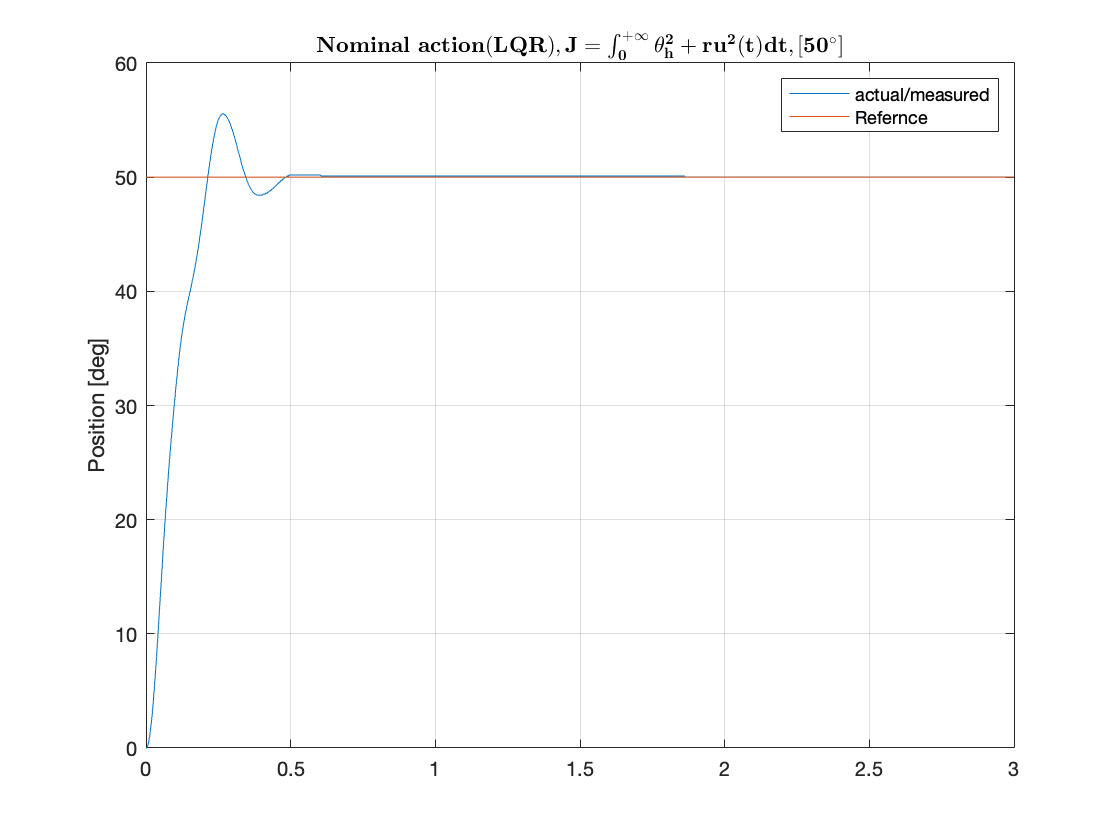

% Set parameters
set_param('SS_eig', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('SS_eig/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig/Enable Integral','Value','0'); % Nominal action ON
set_param('SS_eig/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig/State-space Controller/State feedback gain','gain','lqr_app.K'); % State feedback gain
set_param('SS_eig/State-space Controller/Ki','Gain','0'); % Integral gain

% Run simulation
sim('SS_eig');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position
lqr_app.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
hold on;
plot(lqr_app.t, lqr_app.Ref);
ylabel('Position [deg]');
ylim([0,60]);
grid on;
title('$\bf{ Nominal \ action (LQR), J = \int_0^{+\infty} {\theta_h^2 + ru^2(t)dt}, [50^{\circ}]}$', 'Interpreter',"latex");
legend('actual/measured', 'Refernce');

## 2.4.3 $\bf{J = \int_0^{+\infty} {x^T(t)Qx(t) + ru^2(t)dt}}$

% Q,r using Bryson's rule
lqr_app.r_new = 1/100;
lqr_app.Q_diag_elem = [1/(0.3*50*deg2rad)^2 1/(pi/36)^2 0 0];
lqr_app.Q_new = diag(lqr_app.Q_diag_elem);

% State-feedback K
lqr_app.K_new = lqr(lqr_app.sysG, lqr_app.Q_new, lqr_app.r_new);

## 2.4.4

#### Simulations results [50°] 

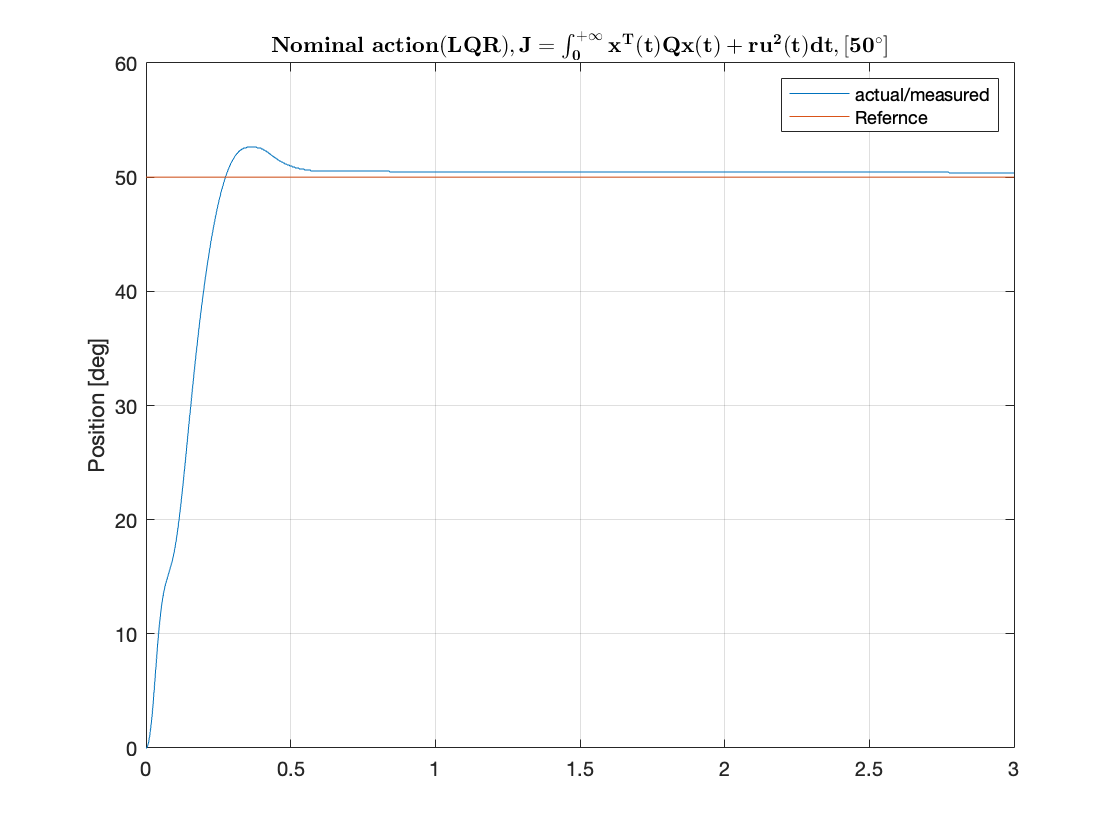

% Set parameters
set_param('SS_eig', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('SS_eig/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig/Enable Integral','Value','0'); % Nominal action ON
set_param('SS_eig/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig/State-space Controller/State feedback gain','gain','lqr_app.K_new'); % State feedback gain
set_param('SS_eig/State-space Controller/Ki','Gain','0'); % Integral gain

% Run simulation
sim('SS_eig');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position
lqr_app.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
hold on;
plot(lqr_app.t, lqr_app.Ref);
ylabel('Position [deg]');
ylim([0,60]);
grid on;
title('$\bf{ Nominal \ action (LQR), J = \int_0^{+\infty} {x^T(t)Qx(t) + ru^2(t)dt}, [50^{\circ}]}$', 'Interpreter',"latex");
legend('actual/measured', 'Refernce');

# INTEGRAL 

## 2.4.5 LQR, $\bf{J = \int_0^{+\infty} {x_i^2(t) + ru^2(t)dt}}$

## Bode Method

function [kp, ki, kd] = BodMet(w_gc,ph_m,P)
[mag_wgc, phm_wgc] = bode(P,w_gc); % gain,phase of P(iw_gc)
deltaK = 1/mag_wgc; % DeltaK
deltaPhi = -180 + ph_m - phm_wgc; % DeltaPhi
kp = deltaK * cosd(deltaPhi); % K_p
T_d = (tand(deltaPhi) + sqrt(tand(deltaPhi)^2 + 1))/(2*w_gc); % T_d
T_i = 4*T_d; % T_i
ki = kp/T_i; % K_i
kd = kp*T_d; % K_d
end